# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       ex1_companion.mlx       gradientDescentMulti.m  warmUpExercise.m        
..                      ex1data1.txt            lib                     
computeCost.m           ex1data2.txt            normalEqn.m             
computeCostMulti.m      featureNormalize.m      plotData.m              
ex1.mlx                 gradientDescent.m       submit.m                



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

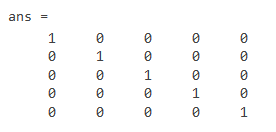

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

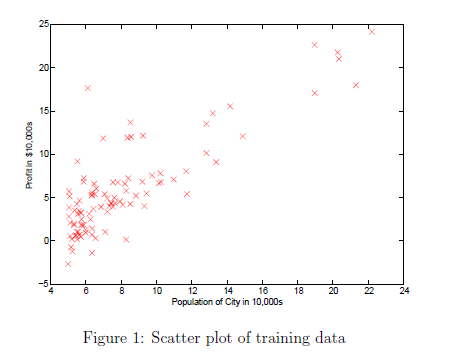

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

n = 2

J = 32.0727

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

n = 2

J = 54.2425

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

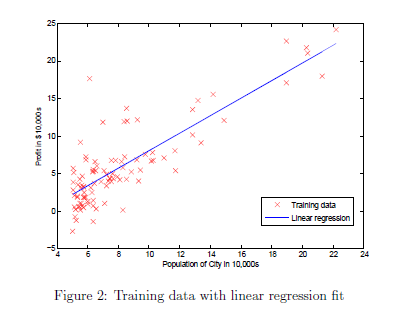    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

n = 2

J = 6.7372

n = 2

J = 5.9316

n = 2

J = 5.9012

n = 2

J = 5.8952

n = 2

J = 5.8901

n = 2

J = 5.8850

n = 2

J = 5.8799

n = 2

J = 5.8749

n = 2

J = 5.8698

n = 2

J = 5.8648

n = 2

J = 5.8598

n = 2

J = 5.8548

n = 2

J = 5.8499

n = 2

J = 5.8449

n = 2

J = 5.8400

n = 2

J = 5.8351

n = 2

J = 5.8302

n = 2

J = 5.8253

n = 2

J = 5.8205

n = 2

J = 5.8156

n = 2

J = 5.8108

n = 2

J = 5.8060

n = 2

J = 5.8012

n = 2

J = 5.7965

n = 2

J = 5.7917

n = 2

J = 5.7870

n = 2

J = 5.7822

n = 2

J = 5.7775

n = 2

J = 5.7729

n = 2

J = 5.7682

n = 2

J = 5.7635

n = 2

J = 5.7589

n = 2

J = 5.7543

n = 2

J = 5.7497

n = 2

J = 5.7451

n = 2

J = 5.7405

n = 2

J = 5.7360

n = 2

J = 5.7315

n = 2

J = 5.7269

n = 2

J = 5.7224

n = 2

J = 5.7179

n = 2

J = 5.7135

n = 2

J = 5.7090

n = 2

J = 5.7046

n = 2

J = 5.7002

n = 2

J = 5.6958

n = 2

J = 5.6914

n = 2

J = 5.6870

n = 2

J = 5.6826

n = 2

J = 5.6783

n = 2

J = 5.6740

n = 2

J = 5.6697

n = 2

J = 5.6654

n = 2

J = 5.6611

n = 2

J = 5.6568

n = 2

J = 5.6526

n = 2

J = 5.6483

n = 2

J = 5.6441

n = 2

J = 5.6399

n = 2

J = 5.6357

n = 2

J = 5.6315

n = 2

J = 5.6274

n = 2

J = 5.6232

n = 2

J = 5.6191

n = 2

J = 5.6150

n = 2

J = 5.6109

n = 2

J = 5.6068

n = 2

J = 5.6027

n = 2

J = 5.5987

n = 2

J = 5.5946

n = 2

J = 5.5906

n = 2

J = 5.5866

n = 2

J = 5.5826

n = 2

J = 5.5786

n = 2

J = 5.5747

n = 2

J = 5.5707

n = 2

J = 5.5668

n = 2

J = 5.5628

n = 2

J = 5.5589

n = 2

J = 5.5550

n = 2

J = 5.5512

n = 2

J = 5.5473

n = 2

J = 5.5434

n = 2

J = 5.5396

n = 2

J = 5.5358

n = 2

J = 5.5319

n = 2

J = 5.5281

n = 2

J = 5.5244

n = 2

J = 5.5206

n = 2

J = 5.5168

n = 2

J = 5.5131

n = 2

J = 5.5094

n = 2

J = 5.5056

n = 2

J = 5.5019

n = 2

J = 5.4982

n = 2

J = 5.4946

n = 2

J = 5.4909

n = 2

J = 5.4872

n = 2

J = 5.4836

n = 2

J = 5.4800

n = 2

J = 5.4764

n = 2

J = 5.4728

n = 2

J = 5.4692

n = 2

J = 5.4656

n = 2

J = 5.4620

n = 2

J = 5.4585

n = 2

J = 5.4550

n = 2

J = 5.4514

n = 2

J = 5.4479

n = 2

J = 5.4444

n = 2

J = 5.4409

n = 2

J = 5.4375

n = 2

J = 5.4340

n = 2

J = 5.4306

n = 2

J = 5.4271

n = 2

J = 5.4237

n = 2

J = 5.4203

n = 2

J = 5.4169

n = 2

J = 5.4135

n = 2

J = 5.4101

n = 2

J = 5.4068

n = 2

J = 5.4034

n = 2

J = 5.4001

n = 2

J = 5.3968

n = 2

J = 5.3935

n = 2

J = 5.3902

n = 2

J = 5.3869

n = 2

J = 5.3836

n = 2

J = 5.3803

n = 2

J = 5.3771

n = 2

J = 5.3738

n = 2

J = 5.3706

n = 2

J = 5.3674

n = 2

J = 5.3642

n = 2

J = 5.3610

n = 2

J = 5.3578

n = 2

J = 5.3546

n = 2

J = 5.3515

n = 2

J = 5.3483

n = 2

J = 5.3452

n = 2

J = 5.3420

n = 2

J = 5.3389

n = 2

J = 5.3358

n = 2

J = 5.3327

n = 2

J = 5.3296

n = 2

J = 5.3266

n = 2

J = 5.3235

n = 2

J = 5.3205

n = 2

J = 5.3174

n = 2

J = 5.3144

n = 2

J = 5.3114

n = 2

J = 5.3084

n = 2

J = 5.3054

n = 2

J = 5.3024

n = 2

J = 5.2994

n = 2

J = 5.2965

n = 2

J = 5.2935

n = 2

J = 5.2906

n = 2

J = 5.2876

n = 2

J = 5.2847

n = 2

J = 5.2818

n = 2

J = 5.2789

n = 2

J = 5.2760

n = 2

J = 5.2731

n = 2

J = 5.2703

n = 2

J = 5.2674

n = 2

J = 5.2646

n = 2

J = 5.2617

n = 2

J = 5.2589

n = 2

J = 5.2561

n = 2

J = 5.2533

n = 2

J = 5.2505

n = 2

J = 5.2477

n = 2

J = 5.2449

n = 2

J = 5.2422

n = 2

J = 5.2394

n = 2

J = 5.2367

n = 2

J = 5.2339

n = 2

J = 5.2312

n = 2

J = 5.2285

n = 2

J = 5.2258

n = 2

J = 5.2231

n = 2

J = 5.2204

n = 2

J = 5.2177

n = 2

J = 5.2150

n = 2

J = 5.2124

n = 2

J = 5.2097

n = 2

J = 5.2071

n = 2

J = 5.2045

n = 2

J = 5.2018

n = 2

J = 5.1992

n = 2

J = 5.1966

n = 2

J = 5.1940

n = 2

J = 5.1915

n = 2

J = 5.1889

n = 2

J = 5.1863

n = 2

J = 5.1838

n = 2

J = 5.1812

n = 2

J = 5.1787

n = 2

J = 5.1762

n = 2

J = 5.1736

n = 2

J = 5.1711

n = 2

J = 5.1686

n = 2

J = 5.1661

n = 2

J = 5.1637

n = 2

J = 5.1612

n = 2

J = 5.1587

n = 2

J = 5.1563

n = 2

J = 5.1538

n = 2

J = 5.1514

n = 2

J = 5.1489

n = 2

J = 5.1465

n = 2

J = 5.1441

n = 2

J = 5.1417

n = 2

J = 5.1393

n = 2

J = 5.1369

n = 2

J = 5.1346

n = 2

J = 5.1322

n = 2

J = 5.1298

n = 2

J = 5.1275

n = 2

J = 5.1251

n = 2

J = 5.1228

n = 2

J = 5.1205

n = 2

J = 5.1181

n = 2

J = 5.1158

n = 2

J = 5.1135

n = 2

J = 5.1112

n = 2

J = 5.1090

n = 2

J = 5.1067

n = 2

J = 5.1044

n = 2

J = 5.1022

n = 2

J = 5.0999

n = 2

J = 5.0977

n = 2

J = 5.0954

n = 2

J = 5.0932

n = 2

J = 5.0910

n = 2

J = 5.0888

n = 2

J = 5.0866

n = 2

J = 5.0844

n = 2

J = 5.0822

n = 2

J = 5.0800

n = 2

J = 5.0778

n = 2

J = 5.0757

n = 2

J = 5.0735

n = 2

J = 5.0714

n = 2

J = 5.0692

n = 2

J = 5.0671

n = 2

J = 5.0650

n = 2

J = 5.0628

n = 2

J = 5.0607

n = 2

J = 5.0586

n = 2

J = 5.0565

n = 2

J = 5.0544

n = 2

J = 5.0524

n = 2

J = 5.0503

n = 2

J = 5.0482

n = 2

J = 5.0462

n = 2

J = 5.0441

n = 2

J = 5.0421

n = 2

J = 5.0400

n = 2

J = 5.0380

n = 2

J = 5.0360

n = 2

J = 5.0340

n = 2

J = 5.0320

n = 2

J = 5.0300

n = 2

J = 5.0280

n = 2

J = 5.0260

n = 2

J = 5.0240

n = 2

J = 5.0220

n = 2

J = 5.0201

n = 2

J = 5.0181

n = 2

J = 5.0162

n = 2

J = 5.0142

n = 2

J = 5.0123

n = 2

J = 5.0104

n = 2

J = 5.0085

n = 2

J = 5.0065

n = 2

J = 5.0046

n = 2

J = 5.0027

n = 2

J = 5.0008

n = 2

J = 4.9989

n = 2

J = 4.9971

n = 2

J = 4.9952

n = 2

J = 4.9933

n = 2

J = 4.9915

n = 2

J = 4.9896

n = 2

J = 4.9878

n = 2

J = 4.9859

n = 2

J = 4.9841

n = 2

J = 4.9823

n = 2

J = 4.9805

n = 2

J = 4.9786

n = 2

J = 4.9768

n = 2

J = 4.9750

n = 2

J = 4.9732

n = 2

J = 4.9714

n = 2

J = 4.9697

n = 2

J = 4.9679

n = 2

J = 4.9661

n = 2

J = 4.9644

n = 2

J = 4.9626

n = 2

J = 4.9609

n = 2

J = 4.9591

n = 2

J = 4.9574

n = 2

J = 4.9556

n = 2

J = 4.9539

n = 2

J = 4.9522

n = 2

J = 4.9505

n = 2

J = 4.9488

n = 2

J = 4.9471

n = 2

J = 4.9454

n = 2

J = 4.9437

n = 2

J = 4.9420

n = 2

J = 4.9404

n = 2

J = 4.9387

n = 2

J = 4.9370

n = 2

J = 4.9354

n = 2

J = 4.9337

n = 2

J = 4.9321

n = 2

J = 4.9304

n = 2

J = 4.9288

n = 2

J = 4.9272

n = 2

J = 4.9255

n = 2

J = 4.9239

n = 2

J = 4.9223

n = 2

J = 4.9207

n = 2

J = 4.9191

n = 2

J = 4.9175

n = 2

J = 4.9159

n = 2

J = 4.9144

n = 2

J = 4.9128

n = 2

J = 4.9112

n = 2

J = 4.9096

n = 2

J = 4.9081

n = 2

J = 4.9065

n = 2

J = 4.9050

n = 2

J = 4.9034

n = 2

J = 4.9019

n = 2

J = 4.9004

n = 2

J = 4.8989

n = 2

J = 4.8973

n = 2

J = 4.8958

n = 2

J = 4.8943

n = 2

J = 4.8928

n = 2

J = 4.8913

n = 2

J = 4.8898

n = 2

J = 4.8883

n = 2

J = 4.8868

n = 2

J = 4.8854

n = 2

J = 4.8839

n = 2

J = 4.8824

n = 2

J = 4.8810

n = 2

J = 4.8795

n = 2

J = 4.8781

n = 2

J = 4.8766

n = 2

J = 4.8752

n = 2

J = 4.8738

n = 2

J = 4.8723

n = 2

J = 4.8709

n = 2

J = 4.8695

n = 2

J = 4.8681

n = 2

J = 4.8667

n = 2

J = 4.8653

n = 2

J = 4.8639

n = 2

J = 4.8625

n = 2

J = 4.8611

n = 2

J = 4.8597

n = 2

J = 4.8583

n = 2

J = 4.8569

n = 2

J = 4.8556

n = 2

J = 4.8542

n = 2

J = 4.8528

n = 2

J = 4.8515

n = 2

J = 4.8501

n = 2

J = 4.8488

n = 2

J = 4.8475

n = 2

J = 4.8461

n = 2

J = 4.8448

n = 2

J = 4.8435

n = 2

J = 4.8422

n = 2

J = 4.8408

n = 2

J = 4.8395

n = 2

J = 4.8382

n = 2

J = 4.8369

n = 2

J = 4.8356

n = 2

J = 4.8343

n = 2

J = 4.8330

n = 2

J = 4.8318

n = 2

J = 4.8305

n = 2

J = 4.8292

n = 2

J = 4.8279

n = 2

J = 4.8267

n = 2

J = 4.8254

n = 2

J = 4.8242

n = 2

J = 4.8229

n = 2

J = 4.8217

n = 2

J = 4.8204

n = 2

J = 4.8192

n = 2

J = 4.8180

n = 2

J = 4.8167

n = 2

J = 4.8155

n = 2

J = 4.8143

n = 2

J = 4.8131

n = 2

J = 4.8119

n = 2

J = 4.8107

n = 2

J = 4.8094

n = 2

J = 4.8083

n = 2

J = 4.8071

n = 2

J = 4.8059

n = 2

J = 4.8047

n = 2

J = 4.8035

n = 2

J = 4.8023

n = 2

J = 4.8012

n = 2

J = 4.8000

n = 2

J = 4.7988

n = 2

J = 4.7977

n = 2

J = 4.7965

n = 2

J = 4.7954

n = 2

J = 4.7942

n = 2

J = 4.7931

n = 2

J = 4.7919

n = 2

J = 4.7908

n = 2

J = 4.7897

n = 2

J = 4.7885

n = 2

J = 4.7874

n = 2

J = 4.7863

n = 2

J = 4.7852

n = 2

J = 4.7841

n = 2

J = 4.7830

n = 2

J = 4.7819

n = 2

J = 4.7808

n = 2

J = 4.7797

n = 2

J = 4.7786

n = 2

J = 4.7775

n = 2

J = 4.7764

n = 2

J = 4.7753

n = 2

J = 4.7743

n = 2

J = 4.7732

n = 2

J = 4.7721

n = 2

J = 4.7711

n = 2

J = 4.7700

n = 2

J = 4.7689

n = 2

J = 4.7679

n = 2

J = 4.7668

n = 2

J = 4.7658

n = 2

J = 4.7648

n = 2

J = 4.7637

n = 2

J = 4.7627

n = 2

J = 4.7617

n = 2

J = 4.7606

n = 2

J = 4.7596

n = 2

J = 4.7586

n = 2

J = 4.7576

n = 2

J = 4.7566

n = 2

J = 4.7556

n = 2

J = 4.7546

n = 2

J = 4.7536

n = 2

J = 4.7526

n = 2

J = 4.7516

n = 2

J = 4.7506

n = 2

J = 4.7496

n = 2

J = 4.7486

n = 2

J = 4.7476

n = 2

J = 4.7467

n = 2

J = 4.7457

n = 2

J = 4.7447

n = 2

J = 4.7438

n = 2

J = 4.7428

n = 2

J = 4.7418

n = 2

J = 4.7409

n = 2

J = 4.7399

n = 2

J = 4.7390

n = 2

J = 4.7380

n = 2

J = 4.7371

n = 2

J = 4.7362

n = 2

J = 4.7352

n = 2

J = 4.7343

n = 2

J = 4.7334

n = 2

J = 4.7325

n = 2

J = 4.7315

n = 2

J = 4.7306

n = 2

J = 4.7297

n = 2

J = 4.7288

n = 2

J = 4.7279

n = 2

J = 4.7270

n = 2

J = 4.7261

n = 2

J = 4.7252

n = 2

J = 4.7243

n = 2

J = 4.7234

n = 2

J = 4.7225

n = 2

J = 4.7216

n = 2

J = 4.7207

n = 2

J = 4.7199

n = 2

J = 4.7190

n = 2

J = 4.7181

n = 2

J = 4.7173

n = 2

J = 4.7164

n = 2

J = 4.7155

n = 2

J = 4.7147

n = 2

J = 4.7138

n = 2

J = 4.7130

n = 2

J = 4.7121

n = 2

J = 4.7113

n = 2

J = 4.7104

n = 2

J = 4.7096

n = 2

J = 4.7087

n = 2

J = 4.7079

n = 2

J = 4.7071

n = 2

J = 4.7062

n = 2

J = 4.7054

n = 2

J = 4.7046

n = 2

J = 4.7038

n = 2

J = 4.7030

n = 2

J = 4.7021

n = 2

J = 4.7013

n = 2

J = 4.7005

n = 2

J = 4.6997

n = 2

J = 4.6989

n = 2

J = 4.6981

n = 2

J = 4.6973

n = 2

J = 4.6965

n = 2

J = 4.6957

n = 2

J = 4.6949

n = 2

J = 4.6942

n = 2

J = 4.6934

n = 2

J = 4.6926

n = 2

J = 4.6918

n = 2

J = 4.6910

n = 2

J = 4.6903

n = 2

J = 4.6895

n = 2

J = 4.6887

n = 2

J = 4.6880

n = 2

J = 4.6872

n = 2

J = 4.6865

n = 2

J = 4.6857

n = 2

J = 4.6850

n = 2

J = 4.6842

n = 2

J = 4.6835

n = 2

J = 4.6827

n = 2

J = 4.6820

n = 2

J = 4.6812

n = 2

J = 4.6805

n = 2

J = 4.6798

n = 2

J = 4.6790

n = 2

J = 4.6783

n = 2

J = 4.6776

n = 2

J = 4.6769

n = 2

J = 4.6761

n = 2

J = 4.6754

n = 2

J = 4.6747

n = 2

J = 4.6740

n = 2

J = 4.6733

n = 2

J = 4.6726

n = 2

J = 4.6719

n = 2

J = 4.6712

n = 2

J = 4.6705

n = 2

J = 4.6698

n = 2

J = 4.6691

n = 2

J = 4.6684

n = 2

J = 4.6677

n = 2

J = 4.6670

n = 2

J = 4.6663

n = 2

J = 4.6656

n = 2

J = 4.6650

n = 2

J = 4.6643

n = 2

J = 4.6636

n = 2

J = 4.6629

n = 2

J = 4.6623

n = 2

J = 4.6616

n = 2

J = 4.6609

n = 2

J = 4.6603

n = 2

J = 4.6596

n = 2

J = 4.6590

n = 2

J = 4.6583

n = 2

J = 4.6577

n = 2

J = 4.6570

n = 2

J = 4.6564

n = 2

J = 4.6557

n = 2

J = 4.6551

n = 2

J = 4.6544

n = 2

J = 4.6538

n = 2

J = 4.6531

n = 2

J = 4.6525

n = 2

J = 4.6519

n = 2

J = 4.6513

n = 2

J = 4.6506

n = 2

J = 4.6500

n = 2

J = 4.6494

n = 2

J = 4.6488

n = 2

J = 4.6481

n = 2

J = 4.6475

n = 2

J = 4.6469

n = 2

J = 4.6463

n = 2

J = 4.6457

n = 2

J = 4.6451

n = 2

J = 4.6445

n = 2

J = 4.6439

n = 2

J = 4.6433

n = 2

J = 4.6427

n = 2

J = 4.6421

n = 2

J = 4.6415

n = 2

J = 4.6409

n = 2

J = 4.6403

n = 2

J = 4.6397

n = 2

J = 4.6391

n = 2

J = 4.6385

n = 2

J = 4.6380

n = 2

J = 4.6374

n = 2

J = 4.6368

n = 2

J = 4.6362

n = 2

J = 4.6356

n = 2

J = 4.6351

n = 2

J = 4.6345

n = 2

J = 4.6339

n = 2

J = 4.6334

n = 2

J = 4.6328

n = 2

J = 4.6322

n = 2

J = 4.6317

n = 2

J = 4.6311

n = 2

J = 4.6306

n = 2

J = 4.6300

n = 2

J = 4.6295

n = 2

J = 4.6289

n = 2

J = 4.6284

n = 2

J = 4.6278

n = 2

J = 4.6273

n = 2

J = 4.6267

n = 2

J = 4.6262

n = 2

J = 4.6257

n = 2

J = 4.6251

n = 2

J = 4.6246

n = 2

J = 4.6241

n = 2

J = 4.6235

n = 2

J = 4.6230

n = 2

J = 4.6225

n = 2

J = 4.6220

n = 2

J = 4.6214

n = 2

J = 4.6209

n = 2

J = 4.6204

n = 2

J = 4.6199

n = 2

J = 4.6194

n = 2

J = 4.6189

n = 2

J = 4.6183

n = 2

J = 4.6178

n = 2

J = 4.6173

n = 2

J = 4.6168

n = 2

J = 4.6163

n = 2

J = 4.6158

n = 2

J = 4.6153

n = 2

J = 4.6148

n = 2

J = 4.6143

n = 2

J = 4.6138

n = 2

J = 4.6133

n = 2

J = 4.6128

n = 2

J = 4.6123

n = 2

J = 4.6119

n = 2

J = 4.6114

n = 2

J = 4.6109

n = 2

J = 4.6104

n = 2

J = 4.6099

n = 2

J = 4.6094

n = 2

J = 4.6090

n = 2

J = 4.6085

n = 2

J = 4.6080

n = 2

J = 4.6076

n = 2

J = 4.6071

n = 2

J = 4.6066

n = 2

J = 4.6061

n = 2

J = 4.6057

n = 2

J = 4.6052

n = 2

J = 4.6048

n = 2

J = 4.6043

n = 2

J = 4.6038

n = 2

J = 4.6034

n = 2

J = 4.6029

n = 2

J = 4.6025

n = 2

J = 4.6020

n = 2

J = 4.6016

n = 2

J = 4.6011

n = 2

J = 4.6007

n = 2

J = 4.6002

n = 2

J = 4.5998

n = 2

J = 4.5993

n = 2

J = 4.5989

n = 2

J = 4.5985

n = 2

J = 4.5980

n = 2

J = 4.5976

n = 2

J = 4.5972

n = 2

J = 4.5967

n = 2

J = 4.5963

n = 2

J = 4.5959

n = 2

J = 4.5954

n = 2

J = 4.5950

n = 2

J = 4.5946

n = 2

J = 4.5942

n = 2

J = 4.5937

n = 2

J = 4.5933

n = 2

J = 4.5929

n = 2

J = 4.5925

n = 2

J = 4.5921

n = 2

J = 4.5916

n = 2

J = 4.5912

n = 2

J = 4.5908

n = 2

J = 4.5904

n = 2

J = 4.5900

n = 2

J = 4.5896

n = 2

J = 4.5892

n = 2

J = 4.5888

n = 2

J = 4.5884

n = 2

J = 4.5880

n = 2

J = 4.5876

n = 2

J = 4.5872

n = 2

J = 4.5868

n = 2

J = 4.5864

n = 2

J = 4.5860

n = 2

J = 4.5856

n = 2

J = 4.5852

n = 2

J = 4.5848

n = 2

J = 4.5844

n = 2

J = 4.5840

n = 2

J = 4.5837

n = 2

J = 4.5833

n = 2

J = 4.5829

n = 2

J = 4.5825

n = 2

J = 4.5821

n = 2

J = 4.5818

n = 2

J = 4.5814

n = 2

J = 4.5810

n = 2

J = 4.5806

n = 2

J = 4.5803

n = 2

J = 4.5799

n = 2

J = 4.5795

n = 2

J = 4.5791

n = 2

J = 4.5788

n = 2

J = 4.5784

n = 2

J = 4.5780

n = 2

J = 4.5777

n = 2

J = 4.5773

n = 2

J = 4.5770

n = 2

J = 4.5766

n = 2

J = 4.5762

n = 2

J = 4.5759

n = 2

J = 4.5755

n = 2

J = 4.5752

n = 2

J = 4.5748

n = 2

J = 4.5745

n = 2

J = 4.5741

n = 2

J = 4.5738

n = 2

J = 4.5734

n = 2

J = 4.5731

n = 2

J = 4.5727

n = 2

J = 4.5724

n = 2

J = 4.5720

n = 2

J = 4.5717

n = 2

J = 4.5713

n = 2

J = 4.5710

n = 2

J = 4.5707

n = 2

J = 4.5703

n = 2

J = 4.5700

n = 2

J = 4.5697

n = 2

J = 4.5693

n = 2

J = 4.5690

n = 2

J = 4.5687

n = 2

J = 4.5683

n = 2

J = 4.5680

n = 2

J = 4.5677

n = 2

J = 4.5673

n = 2

J = 4.5670

n = 2

J = 4.5667

n = 2

J = 4.5664

n = 2

J = 4.5660

n = 2

J = 4.5657

n = 2

J = 4.5654

n = 2

J = 4.5651

n = 2

J = 4.5648

n = 2

J = 4.5645

n = 2

J = 4.5641

n = 2

J = 4.5638

n = 2

J = 4.5635

n = 2

J = 4.5632

n = 2

J = 4.5629

n = 2

J = 4.5626

n = 2

J = 4.5623

n = 2

J = 4.5620

n = 2

J = 4.5617

n = 2

J = 4.5614

n = 2

J = 4.5611

n = 2

J = 4.5607

n = 2

J = 4.5604

n = 2

J = 4.5601

n = 2

J = 4.5598

n = 2

J = 4.5595

n = 2

J = 4.5592

n = 2

J = 4.5590

n = 2

J = 4.5587

n = 2

J = 4.5584

n = 2

J = 4.5581

n = 2

J = 4.5578

n = 2

J = 4.5575

n = 2

J = 4.5572

n = 2

J = 4.5569

n = 2

J = 4.5566

n = 2

J = 4.5563

n = 2

J = 4.5560

n = 2

J = 4.5558

n = 2

J = 4.5555

n = 2

J = 4.5552

n = 2

J = 4.5549

n = 2

J = 4.5546

n = 2

J = 4.5544

n = 2

J = 4.5541

n = 2

J = 4.5538

n = 2

J = 4.5535

n = 2

J = 4.5532

n = 2

J = 4.5530

n = 2

J = 4.5527

n = 2

J = 4.5524

n = 2

J = 4.5522

n = 2

J = 4.5519

n = 2

J = 4.5516

n = 2

J = 4.5513

n = 2

J = 4.5511

n = 2

J = 4.5508

n = 2

J = 4.5505

n = 2

J = 4.5503

n = 2

J = 4.5500

n = 2

J = 4.5497

n = 2

J = 4.5495

n = 2

J = 4.5492

n = 2

J = 4.5490

n = 2

J = 4.5487

n = 2

J = 4.5484

n = 2

J = 4.5482

n = 2

J = 4.5479

n = 2

J = 4.5477

n = 2

J = 4.5474

n = 2

J = 4.5472

n = 2

J = 4.5469

n = 2

J = 4.5467

n = 2

J = 4.5464

n = 2

J = 4.5462

n = 2

J = 4.5459

n = 2

J = 4.5457

n = 2

J = 4.5454

n = 2

J = 4.5452

n = 2

J = 4.5449

n = 2

J = 4.5447

n = 2

J = 4.5444

n = 2

J = 4.5442

n = 2

J = 4.5440

n = 2

J = 4.5437

n = 2

J = 4.5435

n = 2

J = 4.5432

n = 2

J = 4.5430

n = 2

J = 4.5428

n = 2

J = 4.5425

n = 2

J = 4.5423

n = 2

J = 4.5420

n = 2

J = 4.5418

n = 2

J = 4.5416

n = 2

J = 4.5413

n = 2

J = 4.5411

n = 2

J = 4.5409

n = 2

J = 4.5407

n = 2

J = 4.5404

n = 2

J = 4.5402

n = 2

J = 4.5400

n = 2

J = 4.5397

n = 2

J = 4.5395

n = 2

J = 4.5393

n = 2

J = 4.5391

n = 2

J = 4.5388

n = 2

J = 4.5386

n = 2

J = 4.5384

n = 2

J = 4.5382

n = 2

J = 4.5380

n = 2

J = 4.5377

n = 2

J = 4.5375

n = 2

J = 4.5373

n = 2

J = 4.5371

n = 2

J = 4.5369

n = 2

J = 4.5366

n = 2

J = 4.5364

n = 2

J = 4.5362

n = 2

J = 4.5360

n = 2

J = 4.5358

n = 2

J = 4.5356

n = 2

J = 4.5354

n = 2

J = 4.5352

n = 2

J = 4.5350

n = 2

J = 4.5347

n = 2

J = 4.5345

n = 2

J = 4.5343

n = 2

J = 4.5341

n = 2

J = 4.5339

n = 2

J = 4.5337

n = 2

J = 4.5335

n = 2

J = 4.5333

n = 2

J = 4.5331

n = 2

J = 4.5329

n = 2

J = 4.5327

n = 2

J = 4.5325

n = 2

J = 4.5323

n = 2

J = 4.5321

n = 2

J = 4.5319

n = 2

J = 4.5317

n = 2

J = 4.5315

n = 2

J = 4.5313

n = 2

J = 4.5311

n = 2

J = 4.5309

n = 2

J = 4.5307

n = 2

J = 4.5305

n = 2

J = 4.5303

n = 2

J = 4.5301

n = 2

J = 4.5299

n = 2

J = 4.5298

n = 2

J = 4.5296

n = 2

J = 4.5294

n = 2

J = 4.5292

n = 2

J = 4.5290

n = 2

J = 4.5288

n = 2

J = 4.5286

n = 2

J = 4.5284

n = 2

J = 4.5283

n = 2

J = 4.5281

n = 2

J = 4.5279

n = 2

J = 4.5277

n = 2

J = 4.5275

n = 2

J = 4.5273

n = 2

J = 4.5272

n = 2

J = 4.5270

n = 2

J = 4.5268

n = 2

J = 4.5266

n = 2

J = 4.5264

n = 2

J = 4.5263

n = 2

J = 4.5261

n = 2

J = 4.5259

n = 2

J = 4.5257

n = 2

J = 4.5256

n = 2

J = 4.5254

n = 2

J = 4.5252

n = 2

J = 4.5250

n = 2

J = 4.5249

n = 2

J = 4.5247

n = 2

J = 4.5245

n = 2

J = 4.5243

n = 2

J = 4.5242

n = 2

J = 4.5240

n = 2

J = 4.5238

n = 2

J = 4.5237

n = 2

J = 4.5235

n = 2

J = 4.5233

n = 2

J = 4.5232

n = 2

J = 4.5230

n = 2

J = 4.5228

n = 2

J = 4.5227

n = 2

J = 4.5225

n = 2

J = 4.5223

n = 2

J = 4.5222

n = 2

J = 4.5220

n = 2

J = 4.5218

n = 2

J = 4.5217

n = 2

J = 4.5215

n = 2

J = 4.5214

n = 2

J = 4.5212

n = 2

J = 4.5210

n = 2

J = 4.5209

n = 2

J = 4.5207

n = 2

J = 4.5206

n = 2

J = 4.5204

n = 2

J = 4.5203

n = 2

J = 4.5201

n = 2

J = 4.5199

n = 2

J = 4.5198

n = 2

J = 4.5196

n = 2

J = 4.5195

n = 2

J = 4.5193

n = 2

J = 4.5192

n = 2

J = 4.5190

n = 2

J = 4.5189

n = 2

J = 4.5187

n = 2

J = 4.5186

n = 2

J = 4.5184

n = 2

J = 4.5183

n = 2

J = 4.5181

n = 2

J = 4.5180

n = 2

J = 4.5178

n = 2

J = 4.5177

n = 2

J = 4.5175

n = 2

J = 4.5174

n = 2

J = 4.5172

n = 2

J = 4.5171

n = 2

J = 4.5170

n = 2

J = 4.5168

n = 2

J = 4.5167

n = 2

J = 4.5165


% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

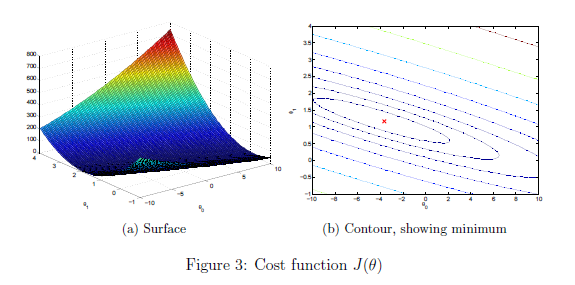

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

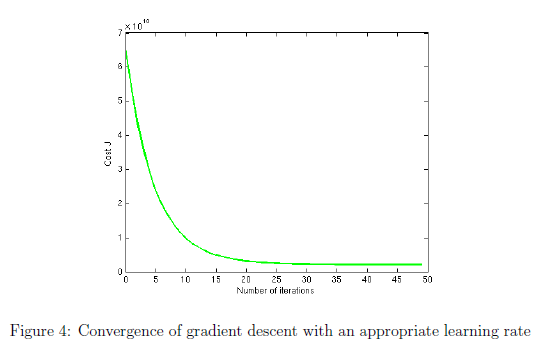

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 0.1;
num_iters = 100;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

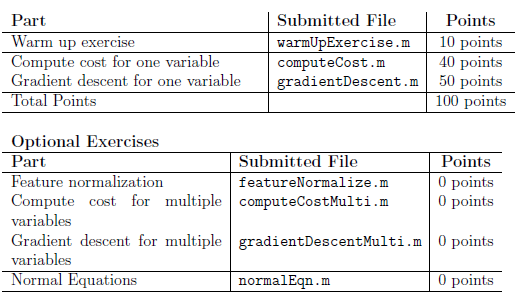

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.